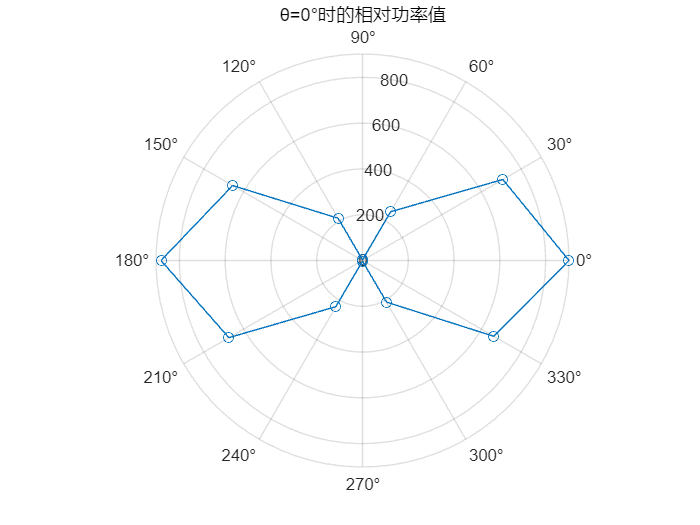

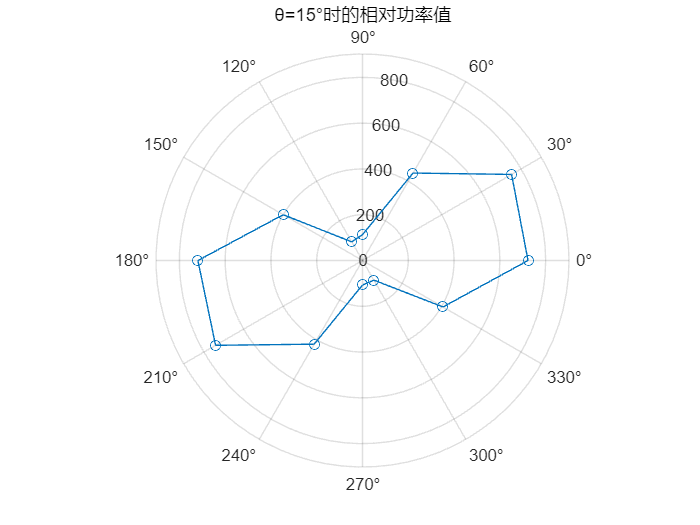

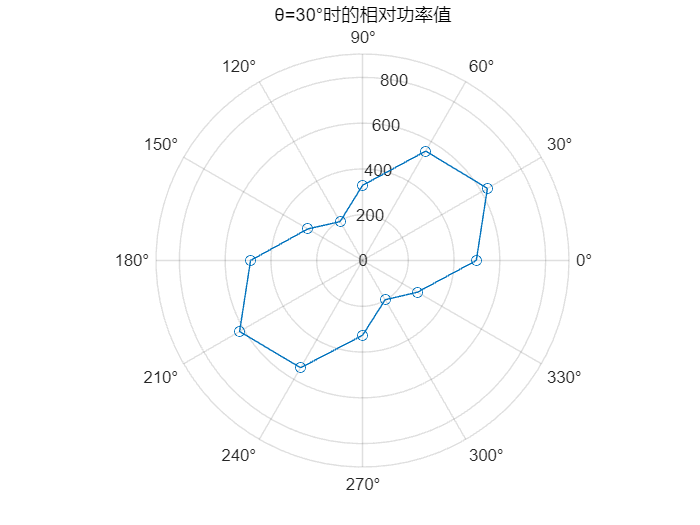

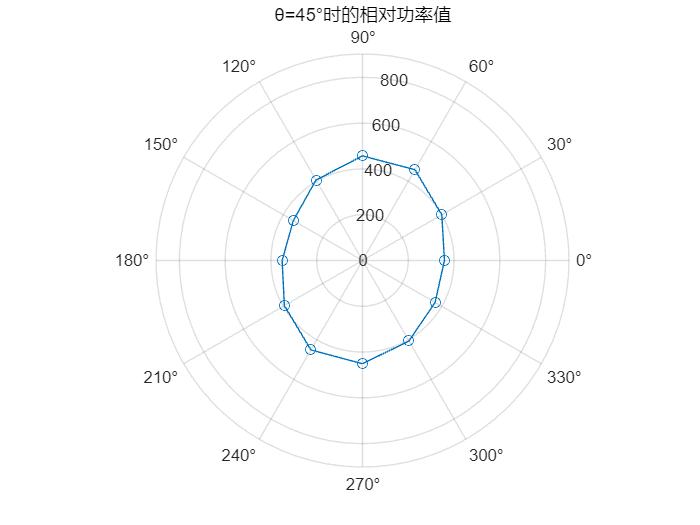

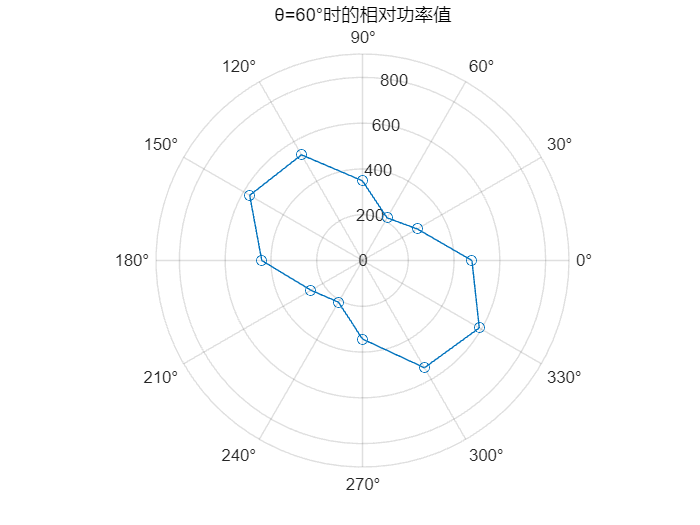

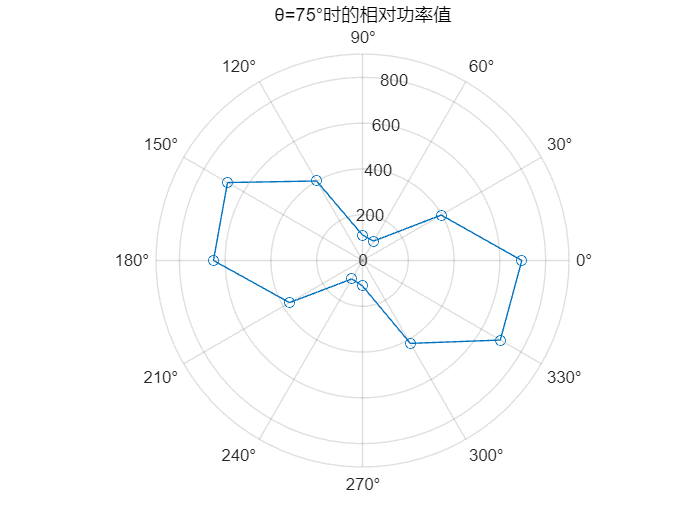

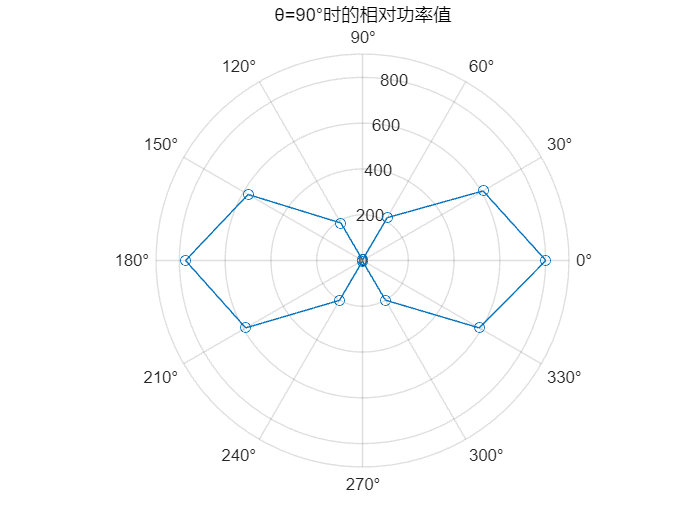

% 加载.mat文件中的数据
data = load('data.mat').data;
data = [data data(1:end, 2)];

% 确保存储目录存在，如果不存在，则创建它
folderName = '极坐标图';
if ~exist(folderName, 'dir')
    mkdir(folderName);
end

% 获取角度theta和角度gamma
theta = data(2:end, 1);  % 第一列，从第二行到最后一行
gamma = data(1, 2:end);  % 第一行，从第二列到最后一列

% 绘制极坐标图
for i = 1:length(theta)
    figure;  % 创建新的图形窗口
    polarplot(deg2rad(gamma), data(i+1, 2:end), 'o-'); % 使用极坐标绘图函数
    thetadeg = theta(i);
    titleText = ['θ=', num2str(thetadeg), '°时的相对功率值'];
    title(titleText);
    ax = gca;
    ax.ThetaTickLabel = arrayfun(@(x) [num2str(x), '°'], 0:30:360, 'UniformOutput', false); % 设置角度标签
    ax.RLim = [0, max(data(2:end, 2:end), [], 'all')]; % 设置极径的范围为数据的最大值
    grid on; % 开启网格

    % 保存图片，文件名为标题文本，特殊字符替换为下划线
    filename = fullfile(folderName, [strrep(titleText, '°', '度'), '.png']);
    saveas(gcf, filename);    
end